# **Live Script for ssVEP analyses**

# **in SPR Webinar *****Frequency-domain analyses of EEG and MEG data: From mathematical foundations to implementation and publication***

# **June 26/27, 2023**

# **Chris Panitz, University of Bremen**

## ***cpanitz@uni-bremen.de, @ChrisPanitz***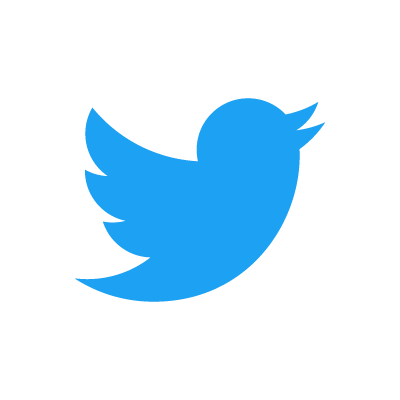

## Background

- Analyses from Panitz, Gundlach, Boylan, Keil, & Müller (2023). Higher amplitudes in steady-state visual evoked potentials driven by square-wave versus sine-wave contrast modulation – A dual-laboratory study. *Psychophysiology, e14287.* [https://doi.org/10.1111/psyp.14287](https://doi.org/10.1111/psyp.14287) 

- Steady-state visual evoked potentials (ssVEPs) are evoked by periodically modulated visual stimuli

- This study flickered colorful patterns in the center of the screen and tested - at different driving frequencies - whether square-wave shaped vs. sine-wave shaped modulation of stimulus contrast evokes different ssVEP amplitudes. We did this in two independen samples from the Universities of Florida & Leipzig.

- This MATLAB script showcases ssVEP-related analysis steps on a single-participant basis. Statistics and plots for group-level data in R can be retrieved from OSF: [https://osf.io/mfc56/](https://osf.io/mfc56/) 

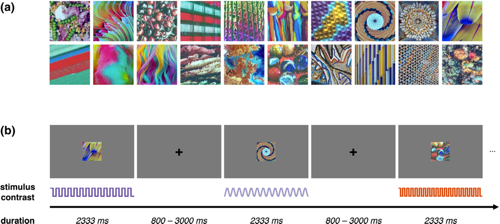

## Demonstrations in this script

- FFT on single-trial vs. averaged ssVEP data

- Sliding window approach to increase (single-trial) SNR

- Hilbert transform

## 1. FFT on single-trial vs. averaged ssVEP data

First, let's load the preprocessed single-trial data for one participant & one condition: modulated with a square-wave function at 6 Hz driving frequency.

% load a high SNR participant
load data/singleTrials_6Hz_square_Oz_greatData.mat

% load an average SNR participant
%load data/singleTrials_6Hz_square_Oz_okayData.mat

% imported matrix: rows = trials; columns = sample points

% parameters
segStart = -600; % in ms relative to stimulus onset
segEnd = 2400;  % in ms relative to stimulus onset
sRate = 500; % sampling rate
fftWin = [300 2300]; % apply FFT to this time window, in ms relative to stimulus onset

Also, let's average across trials to have a look at the ssVEP in the time domain.

% average across trials
avgData = mean(Data,1); 

% plotting in time domain
timeVec = segStart:(1000/sRate):segEnd; % values for x axis
figure, plot(timeVec, avgData);
xlabel('Time relative to stimulus onset (ms)'), ylabel('Amplitude (µV)');

As for intrinsic brain oscillations, we can run an FFT on single-trial data. When seeing the spectrum, note that the data was highpass-filtered at 3 Hz (-3dB).

% Here, we compute normalized spectral amplitudes (i.e., µV/Hz) 
% analogue to the freqtag_FFT.m function from the freqtag toolbox
% (Figueira et al., 2022); it is spelled out here, later we use the
% function as shortcut

% compute some values
deltaFreq = 1000/(fftWin(2)-fftWin(1)); % frequency resolution
nyquistFreq = sRate/2; % Nyquist frequency
fftSamples = (fftWin(1)-segStart)*sRate/1000+1 : (fftWin(2)-segStart)*sRate/1000+1;
nFFT = length(fftSamples); % Number of frequency bins == number of sample points

% compute FFT on single trial data
fftMat = fft(Data(:,fftSamples),[], 2);

% compute and normalize spectral amplitudes (i.e., µV/Hz)
specAmps = abs(fftMat); % spectral amplitude
specAmps = specAmps(:,1:ceil(nFFT/2)); % lose second half of FFT with negative frequencies
specAmps(2:end) = specAmps(2:end) .* 2; % multiply everything by 2 except for DC 
specAmps = specAmps ./ nFFT; % divide by number of frequency bins

% average single-trial spectra
avgSpecAmps = mean(specAmps, 1);

% plot the spectrum
freqVec = 0:deltaFreq:nyquistFreq; % values for x axis
figure, plot(freqVec(1 : 25/deltaFreq+1),avgSpecAmps(1 : 25/deltaFreq+1)); % plot from 0 to 25 Hz
xline(6:6:24, '--'); % mark driving frequency & its harmonics
xlabel('Frequency (Hz)'), ylabel('Spectral Amplitude (µV/Hz)');
title('ERP at Oz');

However, we can also compute FFT using the data averaged in the time domain ("single-subject ERP"). This is because the ssVEP is perfectly phase-locked (ideally - make sure that your presentation device is reliable!). Let's compare the spectrum from this with the averaged spectra from the previous step.

% compute normalized spectral amplitudes for averaged data (i.e., single-participant ERP)
avgDataSpec = freqtag_FFT(avgData(fftSamples), sRate);

% plot averaged spectra vs. spectrum of averaged data 
figure;
hold on;
plot(freqVec(1 : 25/deltaFreq+1),avgSpecAmps(1 : 25/deltaFreq+1)); % DC to 25 Hz on x axis
plot(freqVec(1 : 25/deltaFreq+1),avgDataSpec(1 : 25/deltaFreq+1)); % DC to 25 Hz on x axis
hold off;
xlabel('Frequency (Hz)'), ylabel('Spectral Amplitude (µV/Hz)');
legend('FFT on single trials','FFT on averaged signal');
title('Comparison: averaged single-trial spectra vs spectrum of ERP');

Let's see how it looks on the group level. When comparing conditions, we found that **square-wave** modulation evoked **larger** ssVEP amplitudes than sine-wave modulation in the **6 Hz and 8.57 Hz** condition but not in the 15 Hz condition (graph from paper):

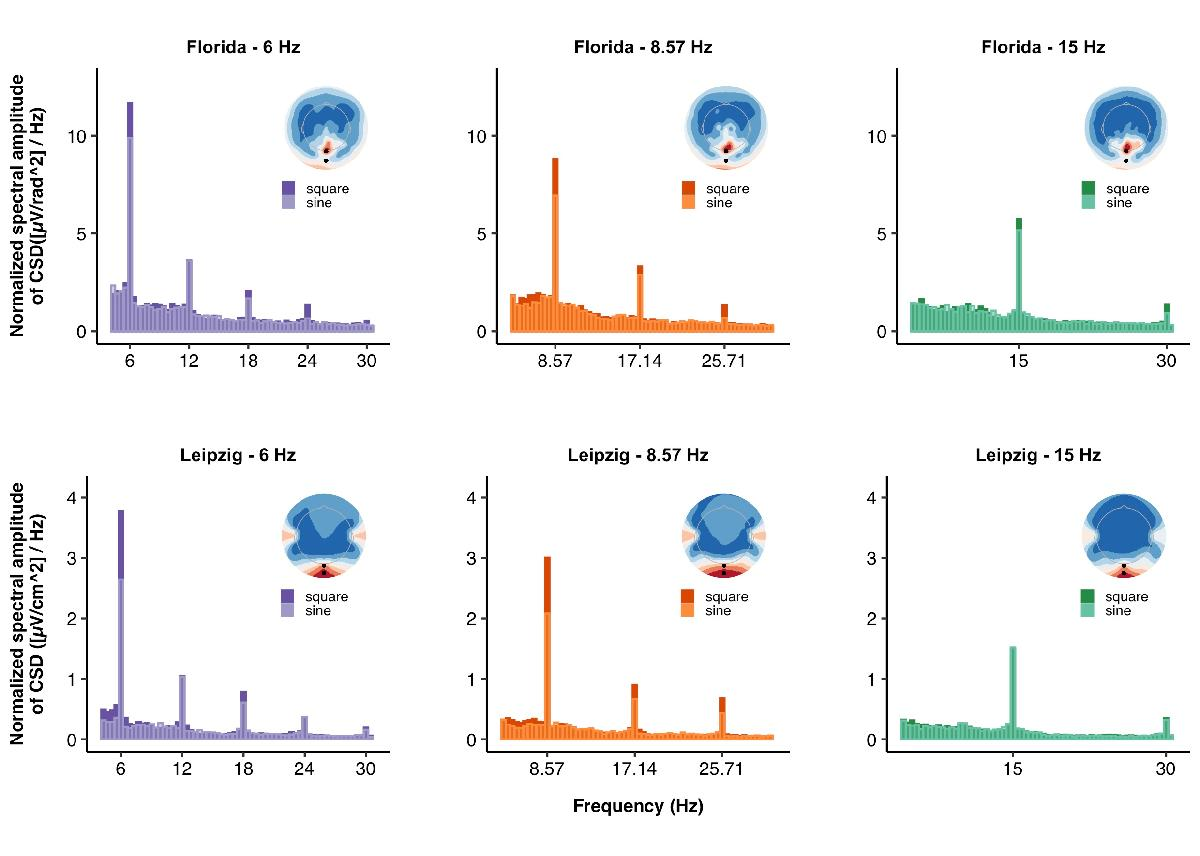

Little experiment: where are the higher harmonics in the time domain data? When investigating spectra to ssVEPs, we typically see increased amplitudes at higher harmonics, i.e., 2 x driving frequency, 3 x driving frequency, etc.. This is because, although the "major cycles" reach their maxima and minima at the driving frequency - they are not perfectly sinusoidal.

% get a part of the ERP with clearly ongoing ssVEP and compute fft (with
% complex output)
erpSignal = avgData(fftSamples);
fftSignal = fft(erpSignal);

% generate FFT spectrum that only consists of the driving frequency parts
fft1f = zeros(1,length(fftSignal));
fft1f([1,13,990]) = fftSignal([1,13,990]);
% and transform it back into time domain
erp1f = ifft(fft1f);

% generate FFT spectrum that only consists of the driving frequency and the
% 2f, 3f, and 4f harmonics
fft1234f = zeros(1,length(fftSignal));
fft1234f([1, 13:12:49, 954:12:990]) = fftSignal([1, 13:12:49, 954:12:990]);
% and transform it back into time domain
erp1234f = ifft(fft1234f);

% compare the ERPs in a plot
figure;
hold on;
plot(erpSignal);
plot(erp1f);
plot(erp1234f);
legend('original ERP','ERP of 1f','ERP of 1f+2f+3f+4f');

## 2. Increasing single-trial SNR: sliding-window averaging

There might be occasions where researchers *need* single-trial information, for example, to show intra-task developments or associations with other responses within participants. Again, the knowledge about the exact driving frequencies is helpful. By applying a moving average on single-trial data, SNR can be increased. More precisely, a window (length = multiple full cycles of driving frequency) is shifted across the signal in the time domain (e.g., 1 cycle per shift) and windows are averaged:

 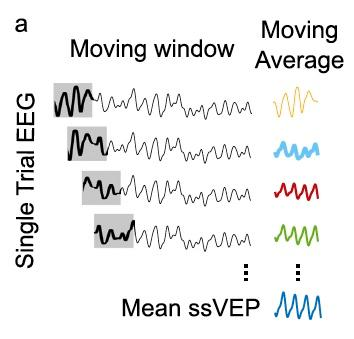

Thigpen et al. (2018), *Journal of Vision*

Let's have a look at the result of sliding window-averaging in the time domain.

% The function we will use expects data dimensions: channels x samples x trials
Data4slidewin = permute(Data,[3,2,1]);

% baseline samples for baseline subtraction (in time domain)
bslSamples = 1:abs(segStart)*sRate/1000;

% run sliding window function from freqtag toolbox
% window length = 4 cycles
% winmat3d = single-trial averages in time domain
[~,winmat3d,~,~] = freqtag_slidewin(Data, ... % EEG data
                                            0, ... % plot windowed data?
                                            bslSamples, ... % baseline samples for correction in time domain
                                            fftSamples, ... % samples of FFT segment
                                            6, ... % frequency of interest
                                            sRate, ... % new sampling rate
                                            sRate, ... % original sampling rate
                                            []); % filename for saving output
% function can also return single-trial amplitude at driving frequency,
% inter-trial phase locking, and SNR

% average 4-cycle averages across trials
avgWinmat = mean(winmat3d,1);

% plot single-trial averages and their average across trials
figure;
hold on;
plot(winmat3d');
plot(avgWinmat,'r','lineWidth',3);
hold off;
xlabel('time in ms'), ylabel('amplitude (µV)');
title('Single-trial sliding window averages');

When inspecting spectra, there should be a clear peak at the driving frequency. Also note the reduced spectral resolution due to shorter time windows (for 4 cycles at 6 Hz ==> 667 ms window length ==> 1.5 Hz frequency resolution).

% compute normalized spectrum for averaged sliding window averages
slideWinSpec = freqtag_FFT(avgWinmat,sRate);

% plot spectrum
deltaFreqSW = 6/4;
freqVecSW = 0:deltaFreqSW:nyquistFreq-deltaFreqSW;
figure, plot(freqVecSW(1 : round(25/deltaFreqSW)),slideWinSpec(1 : round(25/deltaFreqSW)));
xline(6,'--k');
xlabel('frequency (Hz)'), ylabel('amplitude (µV/Hz)');
title('Spectrum of averaged sliding window averages');

And on the group level (see paper supplement):

1) FFT on single-trial data before averaging leads to the same conclusions (square > sine for 6 Hz & 8.57 Hz):

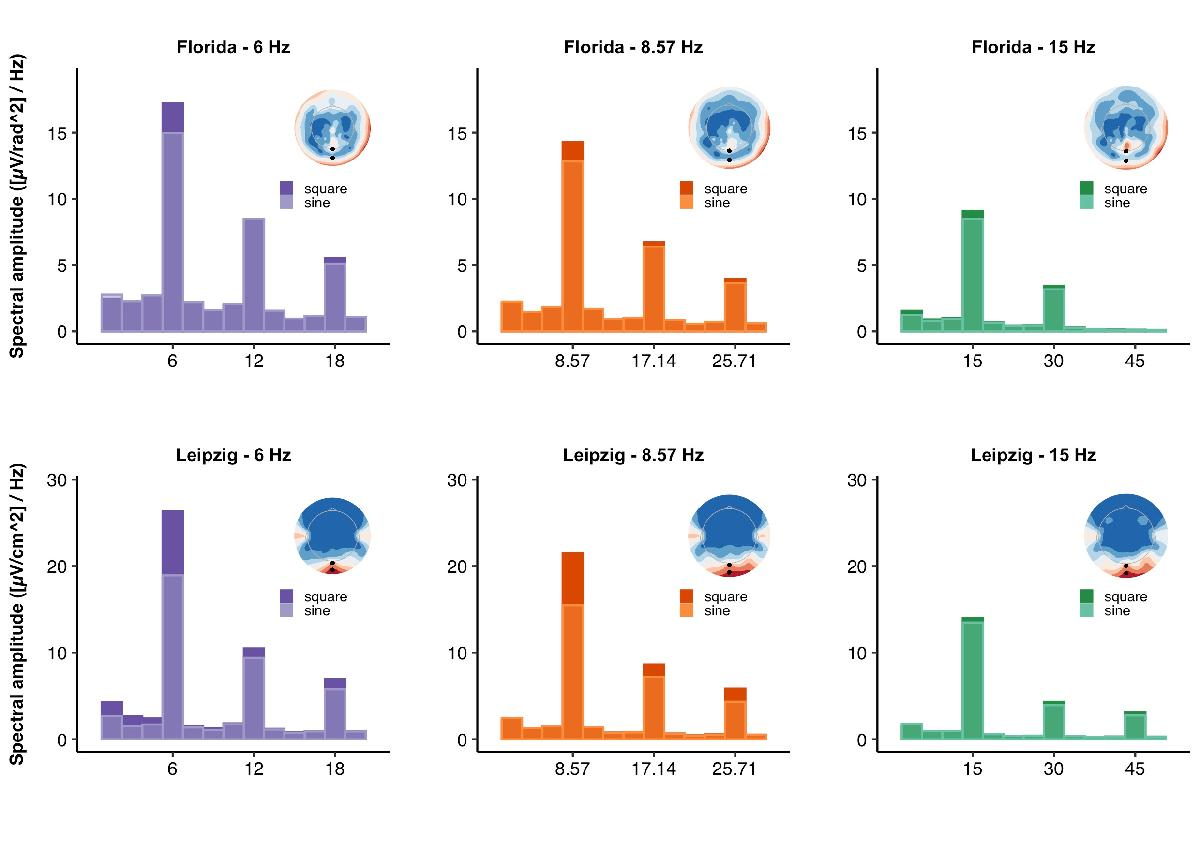

2) **Differences** (and non-differences) between square-wave and sine-wave conditions are **found across trials** (figure in paper supplement):

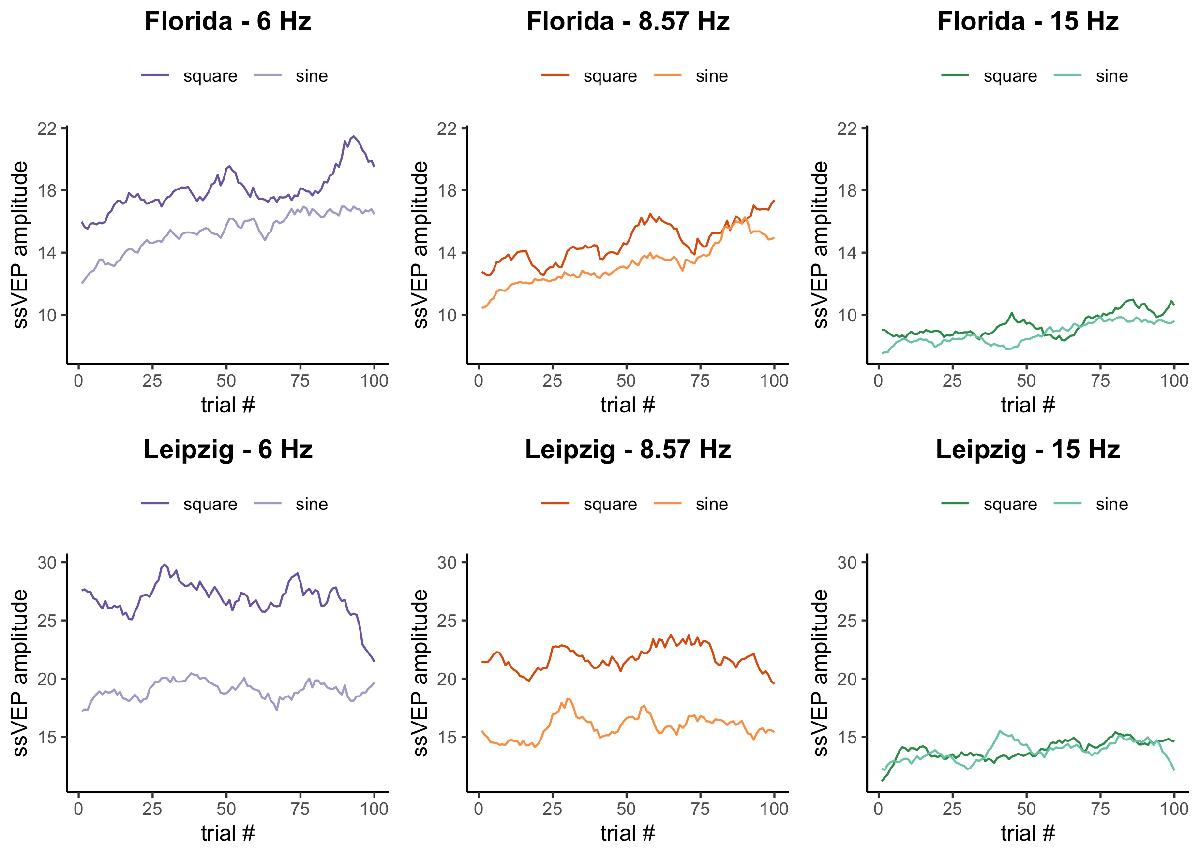

## 3. Hilbert transform

The Hilbert transform can be used to extract instantaneous amplitude and phase from a signal, that is, return values for each sample point in the time domain. This allows to plot time courses. Technically, the Hilbert transform will always return values for the "strongest" frequency that is present in the signal. Therefore, a narrow bandpass filter needs to be applied to time-domain data at the critical frequency - which is known in ssVEP signals.

In preparation for the filtering, we have to taper the data...

% taper data with squared cosine window before filtering
slopeSamp = 200; % 200 samples @ 500 Hz == 400 ms

% create squared cosine window and taper data
squarecos = (cos(pi/2:(pi-pi/2)/slopeSamp:pi-(pi-pi/2)/slopeSamp)).^2;
squarecosfunction = [squarecos ones(1,length(avgData)-length(squarecos).*2) fliplr(squarecos)];
cosinedData = avgData .* squarecosfunction;

% plot original data and data tapered with the squared cosine window
figure;
hold on;
plot(timeVec,avgData);
plot(timeVec,squarecosfunction .* 10 - min(avgData));
plot(timeVec,cosinedData);
hold off;

... create the filters to use in MATLAB ...

%%% Create filters (here: Butterworth)
filterOrder = 4;

% lowpass filter
upperCutoffHz = 5.5; % -3 dB
[Blowpass,Alowpass] = butter(filterOrder, upperCutoffHz/(sRate/2),'low');  
    
% highpass filter
lowerCutoffHz = 6.5; % -3 dB
[Bhighpass,Ahighpass] = butter(filterOrder, lowerCutoffHz/(sRate/2),'high'); 

% visualize filter responses
fvtool(Blowpass,Alowpass);
fvtool(Bhighpass,Ahighpass);

... and finally apply the filters.

%%% Applying the filters
% Filter the data
DataFiltered = filtfilt(Blowpass,Alowpass,avgData);
DataFiltered = filtfilt(Bhighpass,Ahighpass,DataFiltered);

% plot unfiltered vs filtered data
figure;
hold on;
plot(timeVec,avgData);
plot(timeVec,DataFiltered);
hold off;
xlabel('time in ms'), ylabel('amplitude (µV)');
title('unfiltered vs filtered data in time domain');

% plot spectra of filtered vs unfiltered data
figure;
test = freqtag_FFT(DataFiltered(fftSamples),sRate);
hold on;
plot(freqVec(1 : 25/deltaFreq+1), avgDataSpec(1 : 25/deltaFreq+1));
plot(freqVec(1 : 25/deltaFreq+1), test(1 : 25/deltaFreq+1));
hold off;
xlabel('frequency (Hz)'), ylabel('normalized amplitude (µV/Hz)');
title('unfiltered vs filtered data in frequency domain');

After filtering the data, we can compute the Hilbert transform. For this, we need the data in the frequency domain (i.e. the FFT output). Via Hilbert transform we can create the imaginary part of a complex representation of a signal that we only have the real part for. This can be done in an arithmetically more complicated way (by multiplying different parts of the complex spectrum with i and -i; see Mike X Cohen's book on time-frequency analyses, for example) or a bit easier (multiply the positive frequencies by 2 und the negative ones by 0). MATLAB also has the *hilbert.m *function (to my knowledge, it multiplies the spectral data by 2 and 0).

% number of FFT bins (all bins, including positive & negative)
nFFT = length(DataFiltered);

% apply FFT on time domain data to get complex spectrum
fftDataFiltered = fft(DataFiltered);

% Making copy of original spectrum to transform and later add back to the
% original spectrum (as described in Mike Cohen's book)
% copiedFFT = fftDataFiltered * 1i; % make copy and muliply everything by i
% copiedFFT(2:ceil(nFFT/2)) = copiedFFT(2:ceil(nFFT/2)) * -1i; % positive spectrum (not DC or Nyquist) multiplied by -i
% copiedFFT(floor(nFFT/2)+2:end) = copiedFFT(floor(nFFT/2)+2:end) * 1i; % negative spectrum multiplied by i
% we basically have still the same absolute values in the copy but switched
% the signs; so when adding it to the original, the positive frequencies
% double, the negatives cancel out
% hilbertSpectrum = fftDataFiltered + copiedFFT; 

% we can do the transformation in the spectral domain a bit easier (again, DC & Nyquist remain untouched):
hilbertSpectrum = fftDataFiltered;
hilbertSpectrum(2:ceil(nFFT/2)) = hilbertSpectrum(2:ceil(nFFT/2)) .* 2;
hilbertSpectrum(floor(nFFT/2)+2:end) = hilbertSpectrum(floor(nFFT/2)+2:end) .* 0;

% as shown here, we basically eliminated the negative part of the spectrum
figure;
subplot(2,1,1); plot(0:1/3:sRate,abs(fftDataFiltered)); title('Spectrum before transformation');
subplot(2,1,2); plot(0:1/3:sRate,abs(hilbertSpectrum)); title('Spectrum after transformation');


% Finally, we apply an inverse FFT to get back into the time domain with a
% complex signal - which allows to extract amplitude and phase by time
% point
hilbertComplex = ifft(hilbertSpectrum);

% everything here (FFT - spectrum transformation - inverse FFT) is included
% in the hilbert function 
% hilbertComplex = hilbert(DataFiltered) % hilbert function takes time domain data as input


What does the complex signal after Hilbert transform look like? The imaginary part is shifted 90 degrees in phase relative to the real part (remember the cosine & sine parts of a comlpex sine wave or of a Morlet wavelet?). We can look at it in 2D (time x real; time x imaginary) as well as in 3D (time x real x imaginary). The 3D represenation nicely shows how we can extract amplitude and angle (relative to a though line that goes along the time axis through real and imaginary values 0) for each time point: it is the length and orientation of the vector from [time, 0, 0] to the signal at this time point.

% 2D plot of real and imaginary parts agains time
figure;
hold on;
plot(timeVec,real(hilbertComplex));
plot(timeVec,imag(hilbertComplex));
hold off;
xlabel('time in ms'), ylabel('amplitude (µV)');
title('Real and imaginary parts of complex Hilbert transform');
legend('real','imaginary');

% 3D plot with time axis, real part, and imaginary part of the signal
figure, plot3(timeVec,real(hilbertComplex),imag(hilbertComplex));
xlabel('time in ms'), ylabel('real part'), zlabel('imaginary part');
title('Complex signal in time domain')

% to get the 2D planes within the 3D plot
%view([0 90]); % time vs real
%view([0 0]); % time vs imaginary
%view([90 0]); % real vs imaginary


And now, finally, we can extract the amplitude (vector length in 3D space) or phase (vector angle in 3D space) for each time point

% plot Hilbert amplitude by time
figure;
hold on;
plot(timeVec,abs(hilbertComplex));
hold off;
xlabel('time in ms'), ylabel('amplitude (µV)');
title('Amplitude over time via Hilbert transform');

% plot Hilbert phase by time
figure;
hold on;
plot(timeVec,angle(hilbertComplex));
hold off;
xlabel('time in ms'), ylabel('phase (rad)');
title('Phase over time via Hilbert transform');


On the group level, we could show that amplitude **differences** (and non-differences) between square-wave and sine-wave modulation **persist throughout the trial **(figure in the paper supplement):